# MazeAlgo_main

clear; clc;

## General maze

Algorithm converged.


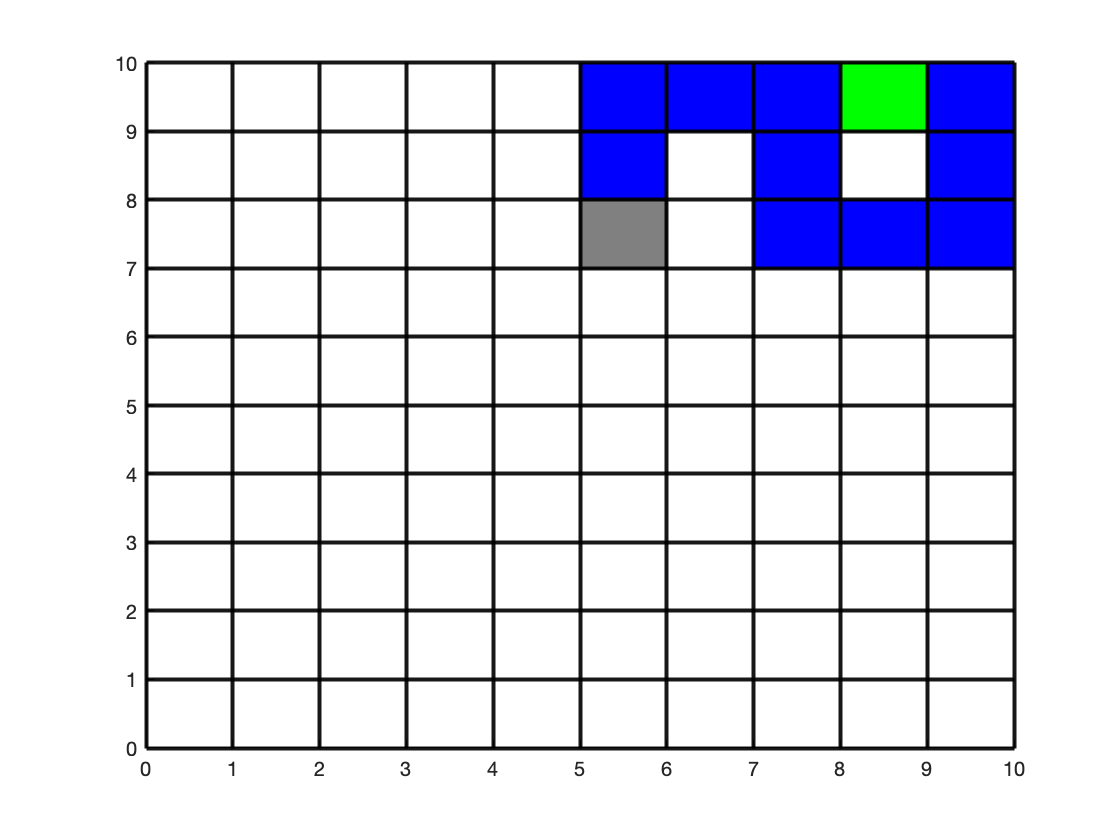

num_turns = 5;
path_length = 10; 
genMaze(num_turns, path_length)

## More complicated maze with more iterations

path does not satisfy parameters.


path does not satisfy parameters.


path does not satisfy parameters.


path does not satisfy parameters.


path does not satisfy parameters.


path does not satisfy parameters.


path does not satisfy parameters.


path does not satisfy parameters.


path does not satisfy parameters.


path does not satisfy parameters.


path does not satisfy parameters.


path does not satisfy parameters.


path does not satisfy parameters.


path does not satisfy parameters.


path does not satisfy parameters.


path does not satisfy parameters.


Algorithm converged.


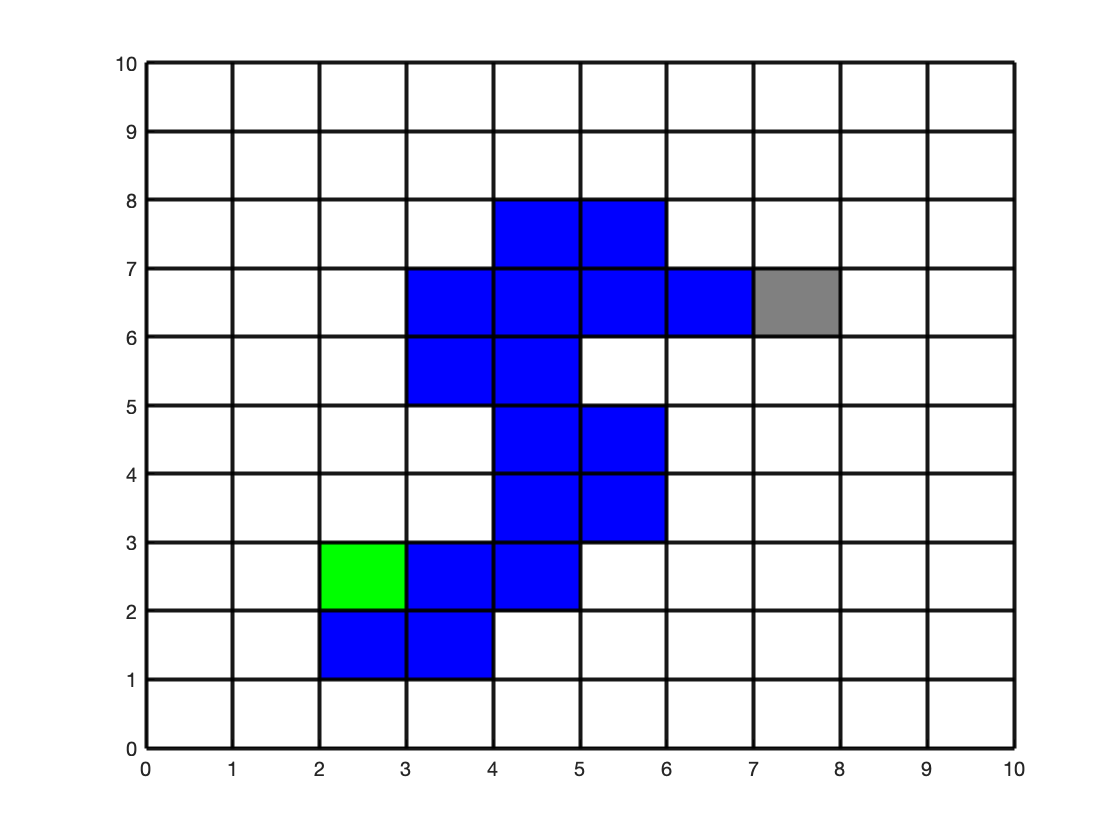

num_turns = 15;
path_length=16;
genMaze(num_turns, path_length, 'maxIter',1e3)

## Maze that isn't a square

Algorithm converged.


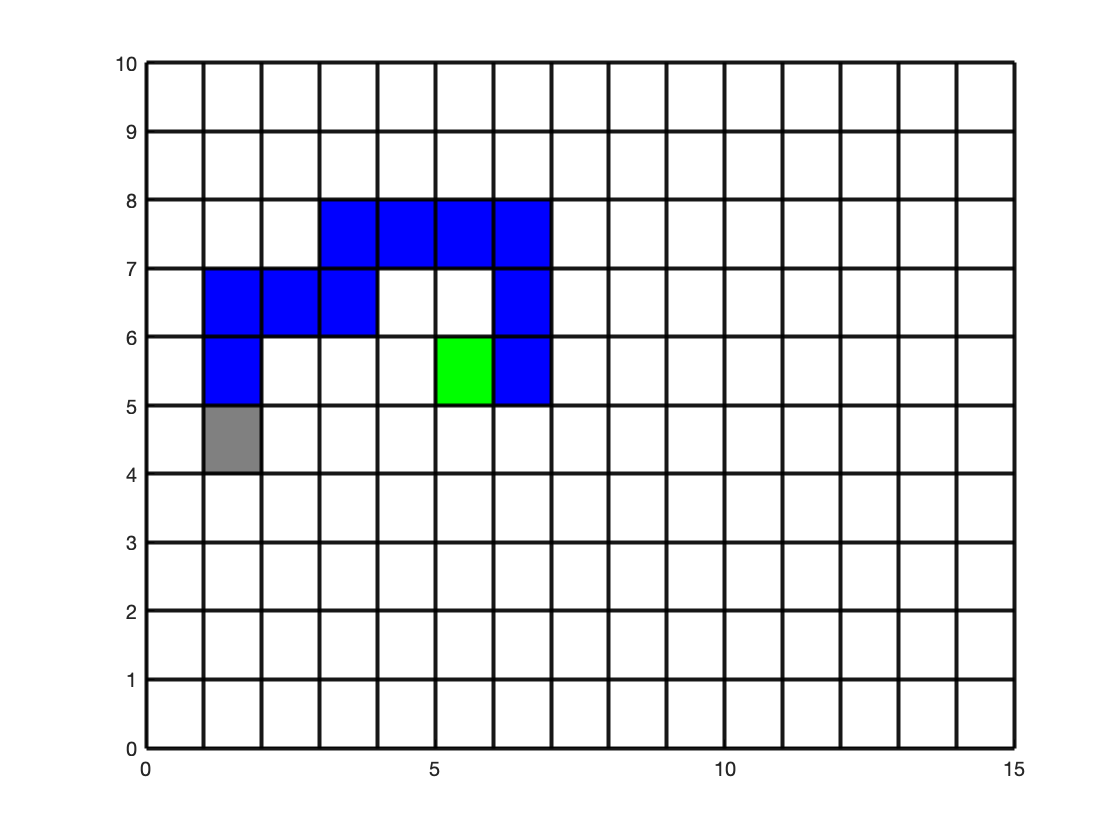

num_turns = 5;
path_length=10;
gridX = 15;
genMaze(num_turns, path_length, 'gridX',gridX)

## Widget inputs

path does not satisfy parameters.


Algorithm converged.


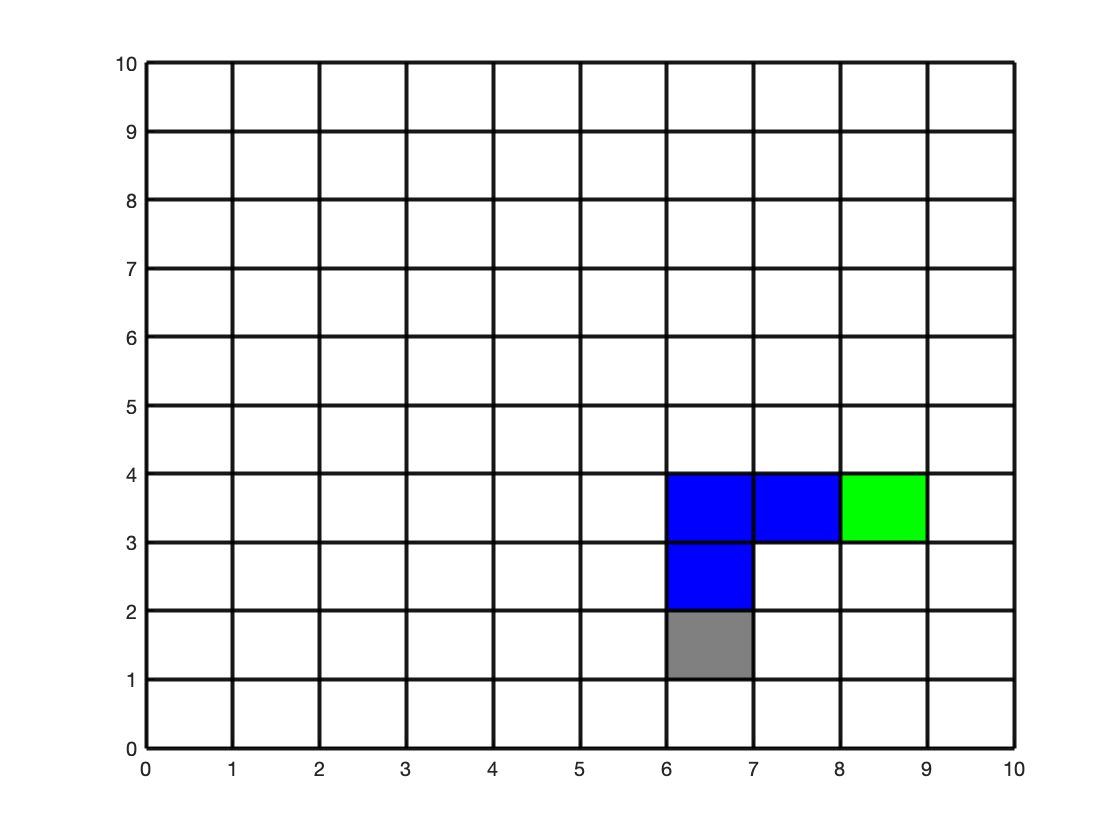

turns = 1;
path = 3;
gridX = 10;
gridY = 10;
maxIter = 250; 
genMaze(turns, path, gridX, gridY, maxIter)

## Functions

function genMaze(num_turns, path_length, varargin)
%{
Generate random maze 

INPUTS:
num_turns: # of turns 
path_length: # of blocks / spaces to travel 
varargin: 
gridX: x maximum
gridY: y maximum
maxIter: maximum number of iterations

OUTPUT:
Visualization of random maze 
%}

%% Check arguments 
arguments 
    num_turns (1,1) {mustBePositive, mustBeFinite, mustBeReal, ...
        mustBeInteger, mustBeNumeric, mustBeNonempty}
    path_length (1,1) {mustBePositive, mustBeFinite, mustBeReal, ...
        mustBeInteger, mustBeNumeric, mustBeNonempty}
end
arguments (Repeating)
    varargin
end

%% parse 
parsed = inputParser();
addRequired(parsed, 'num_turns'); 
addRequired(parsed, 'path_length'); 
addOptional(parsed, 'gridX', 10, @(x) isscalar(x) & isnumeric(x) ); 
addOptional(parsed, 'gridY', 10, @(x) isscalar(x) & isnumeric(x)); 
addOptional(parsed, 'maxIter', 500, @(x) isscalar(x) & isnumeric(x)); 
parse(parsed, num_turns, path_length, varargin{:}); 

%% Create grid
is_new_path_good = false;
currentIter = 1;
while (is_new_path_good == false)
close all;

% Create a 10 by 10 grid
xgrid = 0:1:parsed.Results.gridX;
ygrid = 0:1:parsed.Results.gridY;

% Initiate random start location 
startX = randi([1 parsed.Results.gridX-1]); 
startY = randi([1 parsed.Results.gridY-1]); 
start_current_position = [startX, startY]; 

% display 10 by 10 grid
 figure(); 
 arrayfun(@(x)xline(x,'k', "LineWidth",2), xgrid);
 arrayfun(@(y)yline(y,'k','LineWidth',2), ygrid);
 hold on
 
% display green start location on grid
arrayfun(@(x)xline(x,'k', "LineWidth",2),xgrid), ...
    (rectangle('Position',[startX,startY,1,1],'FaceColor','g'));

arrayfun(@(y)yline(y,'k','LineWidth',2),ygrid,'UniformOutput', false), ...
    (rectangle('Position',[startX,startY,1,1],'FaceColor','g'));

maze_position = start_current_position;
%% Direction types & randomize directions

% Direction types
N = [0,1];
E = [1,0];
S = [0,-1];
W = [-1,0];

if startX == 9 && startY == 9
    w = [0, 0, 0.50, 0.50]; 
    
elseif startX == 0 
    w = [0.33, 0.33, 0.33, 0];
    
elseif startY == 0
    w = [0.33, 0.33, 0, 0.33];
    
elseif startX == 0 && startY == 0
    w = [0.50, 0.50, 0, 0];
    
elseif startX == 9
    w = [0.33, 0, 0.33, 0.33];
    
elseif startY == 9
    w = [0, 0.33, 0.33, 0.33];
    
elseif startX == 9 && startY == 0
    w = [0, 0, 0.50, 0.50];
    
elseif startX == 0 && startY == 9
    w = [0, 0.50, 0.50, 0];
    
elseif startX ~= 9 || startX ~= 0 && ...
        startY ~= 9 || startY ~= 0
   
    w = [0.25, 0.25, 0.25, 0.25];
    
end

rand_dirc = random_choice([1 2 3 4], w);

if rand_dirc == 1 % North
    new = start_current_position + N; 
elseif rand_dirc == 2 % East
    new = start_current_position + E; 
elseif rand_dirc == 3 % South
    new = start_current_position + S; 
elseif rand_dirc == 4 % west
    new = start_current_position + W; 
end

%maze position
maze_position = [maze_position; new];
%array storing logical values of if parameters are being satisfied
path_array = is_new_path_good +1;
% Create the starting maze block (blue) on the grid
rectangle('Position',[new,1,1], 'FaceColor','b');

% assign new varible 'p' to current x,y coordinates
p = new;

%% Create path

%The total number of segment lengths
Max_lengths = num_turns+1;

%{
 (randi([0,path_length-Max_lengths],1,Max_lengths-1))
    %Returns size [1xMax_lengths-1] vector of random integers
    %Between 0 and path_length - Max_lengths

sort the output of the randi array in order from ascending order
    % returns [1xMax_lengths-1] vector of sorted random values in ascending
    % order

find the diff of ([0, sorted ouput, pth_length - max_length])
    % returns [1 x max_length] vector of segment legnths
    % will find the difference between each element in vector

 +ones(1,Max_lengths)
    % returns [1 x max_length] vector of segment lenghts
    % adds the [1 x max_lengths] vector to the vector of difference values 

%}
c = (diff([0,sort(randi([0,path_length-Max_lengths],1,num_turns)),path_length-Max_lengths])+ones(1,Max_lengths));

% update the new coordinates of maze path
new_path_dirc = p;
% iterate through the length of c
for i = 1:length(c)
% analyze each individual element of 'c' array
    for ii = 1:c(i)
        % When the individual element of 'c' is greater than one
        % create the path, WHEN ITS NOT A TURN
        if c(i) > 1

            %update the value of variable of p
            p = new_path_dirc;

            % substract that individual element by one
            c(i) = c(i) - 1;

        % create path in north direction
            if rand_dirc == 1
            new_path_dirc = p + N;
        % create path in east direction
            elseif rand_dirc == 2
            new_path_dirc = p + E;
        % create path in south direction
            elseif rand_dirc == 3
            new_path_dirc = p + S;
        % create path in west direction
            elseif rand_dirc == 4
            new_path_dirc = p + W;
            end
            %checks for if path is within bounds or overlaps
            if (new_path_dirc(1) < 0 || new_path_dirc(1) > 9 || new_path_dirc(2) < 0 || new_path_dirc(2) > 9) || sum(sum(new_path_dirc == maze_position, 2) == 2) > 0
                is_new_path_good = false;
            else
                is_new_path_good = true;
            end

            if currentIter == parsed.Results.maxIter
                fprintf('Algorithm did not converege. Try again.\n')
                return
            end 
            currentIter = currentIter +1;


maze_position = [maze_position; new_path_dirc];
path_array = [path_array; is_new_path_good];
% create maze path on the grid
rectangle('Position',[new_path_dirc,1,1], 'FaceColor','b');
        end

        % When the element in array c is 1 and not the last segment
        % Create a TURN
        if c(i) == 1 && i ~= Max_lengths
            % decrease the elements in array c by one
            c(i) = c(i) - 1;
            % update the value of p
            p = new_path_dirc;

            % change direction E W
            % when direction of path is either going north or south
            if rand_dirc == 1 || rand_dirc == 3
                % randomly chooses between going east or west
                dirc = random_choice([1 2 3 4], [0 0.50 0 0.50]);
                if dirc == 2 % east
                    new_path_dirc2 = new_path_dirc + E;
                elseif dirc == 4 % west
                    new_path_dirc2 = new_path_dirc + W;
                end
                % update the value of varibale p (coordiantes of the path)
                p = new_path_dirc2;
                % update the value of variable rand-dirc (path direction of the maze)
                rand_dirc = dirc;
                % update the value of variable new_path_dirc
                new_path_dirc = p;

                % change direction N S
                % when direction of path is either going east or west
            elseif rand_dirc == 2 || rand_dirc == 4
                % randomly choose between going north or south
                dirc = random_choice([1 2 3 4], [0.50 0 0.50 0]);
                if dirc == 1 % north
                    new_path_dirc2 = new_path_dirc + N;
                elseif dirc == 3 % south
                    new_path_dirc2 = new_path_dirc + S;
                end
                % update the value of variable p (coordiantes of the path)
                p = new_path_dirc2;
                % update the value of variable rand_dirc (path direction of the maze)
                rand_dirc = dirc;
                % update the value of variable new_path_dirc
                new_path_dirc = p;
            end

            if (new_path_dirc2(1) < 0 || new_path_dirc2(1) > 9 || new_path_dirc2(2) < 0 || new_path_dirc2(2) > 9) || sum(sum(new_path_dirc2 == maze_position, 2 ) == 2) > 0
                is_new_path_good = false;
            else
                is_new_path_good = true;
            end 
            
            if currentIter == parsed.Results.maxIter
             fprintf('Algorithm did not converge. Try Aagin.\n')  
             return
            end
            currentIter = currentIter +1;


maze_position = [maze_position; new_path_dirc2];
path_array = [path_array; is_new_path_good];
% creates the path of maze on the grid
rectangle('Position',[new_path_dirc2,1,1], 'FaceColor','b')

        end


% create the finish grid area
% This at the movement is seperate from the for loop of the path
% therefore will go off thr grid

% update the value of variable new_path_dirc
if c(i) == 1 && i == Max_lengths 
    c(i) = c(i) - 1;
    if rand_dirc == 1 % north
        finish_location = new_path_dirc2 + N; 
    elseif rand_dirc == 2 % east
        finish_location = new_path_dirc2 + E;
    elseif rand_dirc == 3 % south
        finish_location = new_path_dirc2 + S; 
    elseif rand_dirc == 4 % west
        finish_location = new_path_dirc2 + W; 
    end
    
    x = path_array == 0;
    
        if (finish_location(1) < 0 || finish_location(1) > 9 || finish_location(2) < 0 || finish_location(2) > 9) || sum(sum(finish_location == maze_position, 2) == 2) >0 || any(x == 1)
            is_new_path_good = false;
            fprintf('path does not satisfy parameters.\n')
        else
            is_new_path_good = true;
            fprintf('Algorithm converged.\n') 
        end
        if currentIter == parsed.Results.maxIter
          fprintf('Algorithm did not converge. Try again.\nConsider either increasing grid area, increasing maximum number of iterations, decreasing number of turns, or decreasing path length.')
                return
        end
currentIter = currentIter +1; 

maze_position = [maze_position; finish_location];
path_array = [path_array; is_new_path_good];
rectangle('Position',[finish_location,1,1], 'FaceColor',[0.5 0.5 0.5]);
end  
    end
end
end
end

function choice = random_choice(array,w)
%{
Randomly choose 1 value form array with weights q (pseeudo-uniform)
INPUTS:
array: array of values [ N X 1]
w: weights [ N X 1]

OUTPUTS:
choice: element from array
%}

arguments
    array (:,1)
    w (:,1)
end

if length(array) ~= length(w)
    error('Elements of array and w must have smae lengths')
end

choices = array(w~= 0);

rnd = randi([1 length(choices)], 1);

choice = choices(rnd);

end